# Fluxo de carga para redes de distribuição 

- Estrutura radial ou quase radial

- Operação desbalanceada multifásica cm equipamentos  aterrados ou não

- presença de geração dsitribuída

- número de barras e ramos extremamente grandes

O desempenho dos metodos de fluxo de carga desenvolvidos para redes de transmissao pode piorar quando utilizados para análise  de redes de distribuição.

#### Modelo de uma linha de distribuição:

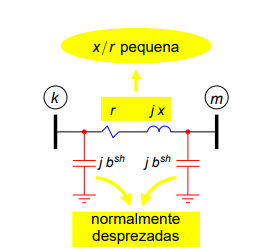

Métodos de eficientes de cálculo de fluxo e carga para redes de distribuição:

- Modificação do método de Newton

- Back-Forward sweep

**Método desacoplado rápido com rotação de eixos: **mudar temporariamente o sistema de referência complexo através da rotação dos eixos real e imaginário de modo que as impedâncias passem a ter relação $\frac{X}{R}$ favorável ao desempenho do MDR

**Método Back-forward sweep:**

- **Arbitrar tensões nodais **$V_k$

- **Calcular corrente nodais **$I_k ={\left(\frac{S_k }{V_k }\right)}^* +Y_k^{\textrm{sh}} V_k$

- **Calcular as correntes nos ramos que conectam os nós k e m **$I_{\textrm{km}} =I_m +\sum I_{\textrm{mj}}$

- **Atualizar as tensões nodais começando pela subestação em direção às barras terminais **$V_m =V_k -Z_{\textrm{km}} I_{\textrm{km}}$

- **Teste de convergencia:  **


$$\max_{k=2,\ldotp \ldotp 4} \left\lbrace \Delta V_k \right\rbrace \le \textrm{tol}\Longrightarrow A\;\textrm{solução}\;\textrm{foi}\;\textrm{obtida}$$
  


$$\max_{k=2,\ldotp \ldotp 4} \left\lbrace \Delta V_k \right\rbrace >\textrm{tol}\Longrightarrow \textrm{Voltar}\;\textrm{ao}\;\textrm{passo}\;2$$
 

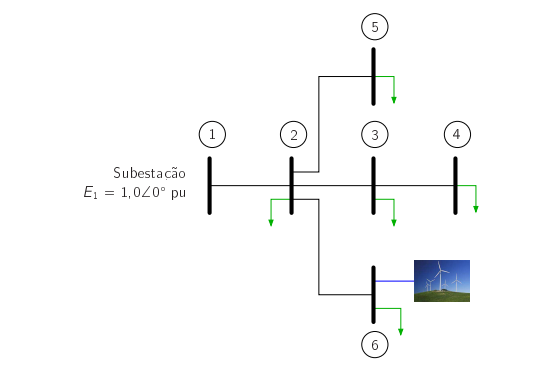

# **Implementação**

% -------------------------------- Q2 Prova --------------------------
%             Env   Rec     Rs[pu]      Xs[pu]  Ysh[pu] Rel_transf_tensao(a)[pu]    Ang_def (rad)

Dados_linha=[ 1      2       0.01      0.005    0.00      1       0;
              2      3       0.06      0.050    0.00      1       0;
              2      4       0.03      0.002    0.00      1       0;
              4      5       0.05      0.002    0.00      1       0;];

%                Barra  Tipo   V      θ      Pi     Qi         Pc      Qc
Dados_barra=[       1     1    1.00   0     0.00    0.00        0.00   0.0;     % Barra 1 tipo 1 → (Vθ) — Barra slack
                    2     3    0.00   0     0.00    0.00        0.50   0.1;     % Barra 2 tipo 3 → (PQ) — Barra de carga
                    3     3    0.00   0     0.00    0.00        1.00   0.6;     % Barra 3 tipo 3 → (PQ) — Barra de carga
                    4     3    0.00   0     0.00    0.00        1.00   0.5;     % Barra 4 tipo 3 → (PQ) — Barra de carga
                    5     3    1.00   0     0.00    0.00        0.80   0.3;];   % Barra 5 tipo 3 → (PQ) — Barra de carga
   

## 1. Extraindo os dados 

% -------------------------------------------
% Dados da linha de transmissão
% -------------------------------------------
Orig =  Dados_linha(:, 1);
Dest =  Dados_linha(:, 2);
Rs   =  Dados_linha(:, 3);
Xs   =  Dados_linha(:, 4);
bsh  =  Dados_linha(:, 5);
a    =  Dados_linha(:, 6);
phi  =  Dados_linha(:, 7);
NumLT =    size(Orig, 1);

% -------------------------------------------
% Dados da barra
% -------------------------------------------
Barra      = Dados_barra(:, 1);
Tipo       = Dados_barra(:, 2);
Vref       = Dados_barra(:, 3);
Theta      = Dados_barra(:, 4);
Pi         = Dados_barra(:, 5);
Qi         = Dados_barra(:, 6);
Pc         = Dados_barra(:, 7);
Qc         = Dados_barra(:, 8);
NumBarras  = size(Dados_barra, 1);

## 3. Implementação do Algoritmo

% --------------------------------------
% Cálculo do Fluxo de Potência para sistema de distribuição
% --------------------------------------

% ----------------------
%  (1) Arbitrar tensões nodais
% ----------------------
V = Vref;

slack = find(Tipo == 1); % Barra Slack (referência) - tensão fixa (V e ângulo)
PV = find(Tipo == 2);    % Barras tipo PV - tensão e potência ativa fixas
PQ = find(Tipo == 3);    % Barras tipo PQ - potência ativa e reativa fixas

V(PQ) = 1;         % Barras PQ começam com V = 1 pu

%% Loop de Iteração
Tol = 1e-6;
max_iter = 100;
iter = 0;

S = (Pi - Pc) + 1i*(Qi - Qc);
Z = Rs + 1i*Xs;

while true
    iter = iter + 1;
    V_ant = V;
    
    %% Passo 1: Cálculo das correntes nodais
    I_nodais = zeros((NumBarras - 1), 1);
    for k = 1:NumBarras
        if Tipo(k) ~= 1 % Não calcula para slack
            
            I_nodais(k) = -conj(S(k)/V(k));
        end
    end
    
    %% Passo 2: Forward sweep - Cálculo das correntes nos ramos
    I_ramos = zeros(NumLT, 1);
    for k = NumLT:-1:1
        m = Dest(k);
        filhos = find(Orig == m); % Ramos que saem de m
        I_ramos(k) = I_nodais(m) + sum(I_ramos(filhos));
    end
    
    %% Passo 3: Backward sweep - Atualização das tensões
    for i = 1:NumLT
        if (Tipo(i) ~= slack)
            k = Orig(i);
            m = Dest(i);
            V(m) = V(k) - Z(i)*I_ramos(i);
            % Ajusta para manter módulo especificado
            if(Tipo(m) == 4)
                V(m) = Vref(m) * exp(1j * angle(V(m))); 
            end
        end
    end


     %% Impressão dos Resultados por Iteração
    fprintf('\n===========================\n');
    fprintf('Iteração %d\n', iter);
    fprintf('===========================\n');
    % 
    % % Potência nas barras
    % fprintf('\nPotência nas barras (S_k):\n');
    % for k = 1:NumBarras
    %     fprintf('Barra %d: S = %.4f + j%.4f pu\n', k, real(S(k)), imag(S(k)));
    % end
    % 
    % % Corrente nodal
    % fprintf('\nCorrentes nodais:\n');
    % for k = 1:NumBarras
    %     if Tipo(k) ~= 1
    %         fprintf('Barra %d: |I| = %.4f pu, Ângulo = %.4f rad \n', k, abs(I_nodais(k)), angle(I_nodais(k)));
    %     else
    %         fprintf('Barra %d (Slack): |I| = 0.0000 pu, Ângulo = 0.0000 rad\n', k);
    %     end
    % end
    % 
    % % Corrente nos ramos
    % fprintf('\nCorrentes nos ramos:\n');
    % for k = 1:NumLT
    %     fprintf('Ramo %d -> %d: |I| = %.4f pu, Ângulo = %.4f rad\n', Orig(k), Dest(k), abs(I_ramos(k)), angle(I_ramos(k)) );
    % end

    % % Tensões nas barras
    % fprintf('\nTensões nas barras (V_k):\n');
    % for k = 1:NumBarras
    %     fprintf('Barra %d: |V| = %.4f pu, Ângulo = %.4f rad \n', k, abs(V(k)), angle(V(k)) );
    % end


    % ----------------------------
    % (4) Verifica se convergiu
    % ----------------------------
    %% Verificação de Convergência
    erro_iter = abs(V - V_ant);
    erro = max(erro_iter);
    
    fprintf('\n--- Erros na Iteração %d ---\n', iter);
    for k = 1:NumBarras
        fprintf('Barra %d: |V| = %.4f pu, Ângulo = %.4f rad -> Erro = %.6f pu\n', ...
                k, abs(V(k)), angle(V(k)) * 180/pi, erro_iter(k));
    end
    
    fprintf('\nErro máximo na iteração %d = %.8f\n', iter, erro);

    
    % ----------------------------
    % Verifica se excedeu o número máximo de iterações
    % ----------------------------
    if iter >= max_iter
        fprintf('Número máximo de iterações atingido.\n');
        break;
    end

    if max(erro < Tol)
        break
    end

end

Iteração 1



--- Erros na Iteração 1 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.9101 pu, Ângulo = -0.8814 rad -> Erro = 0.091082 pu
Barra 4: |V| = 0.9446 pu, Ângulo = 1.2375 rad -> Erro = 0.059224 pu
Barra 5: |V| = 0.9044 pu, Ângulo = 2.1417 rad -> Erro = 0.101965 pu



Erro máximo na iteração 1 = 0.10196509


Iteração 2



--- Erros na Iteração 2 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.9010 pu, Ângulo = -0.8814 rad -> Erro = 0.009115 pu
Barra 4: |V| = 0.9396 pu, Ângulo = 1.2324 rad -> Erro = 0.004997 pu
Barra 5: |V| = 0.8946 pu, Ângulo = 2.1356 rad -> Erro = 0.009816 pu



Erro máximo na iteração 2 = 0.00981642


Iteração 3



--- Erros na Iteração 3 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.9000 pu, Ângulo = -0.8913 rad -> Erro = 0.001013 pu
Barra 4: |V| = 0.9392 pu, Ângulo = 1.2424 rad -> Erro = 0.000500 pu
Barra 5: |V| = 0.8937 pu, Ângulo = 2.1573 rad -> Erro = 0.001019 pu



Erro máximo na iteração 3 = 0.00101860


Iteração 4



--- Erros na Iteração 4 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.8999 pu, Ângulo = -0.8913 rad -> Erro = 0.000114 pu
Barra 4: |V| = 0.9391 pu, Ângulo = 1.2424 rad -> Erro = 0.000052 pu
Barra 5: |V| = 0.8935 pu, Ângulo = 2.1573 rad -> Erro = 0.000106 pu



Erro máximo na iteração 4 = 0.00011373


Iteração 5



--- Erros na Iteração 5 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.8999 pu, Ângulo = -0.8914 rad -> Erro = 0.000013 pu
Barra 4: |V| = 0.9391 pu, Ângulo = 1.2425 rad -> Erro = 0.000005 pu
Barra 5: |V| = 0.8935 pu, Ângulo = 2.1575 rad -> Erro = 0.000011 pu



Erro máximo na iteração 5 = 0.00001279


Iteração 6



--- Erros na Iteração 6 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.8999 pu, Ângulo = -0.8914 rad -> Erro = 0.000001 pu
Barra 4: |V| = 0.9391 pu, Ângulo = 1.2425 rad -> Erro = 0.000001 pu
Barra 5: |V| = 0.8935 pu, Ângulo = 2.1575 rad -> Erro = 0.000001 pu



Erro máximo na iteração 6 = 0.00000144


Iteração 7



--- Erros na Iteração 7 ---


Barra 1: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 2: |V| = 1.0000 pu, Ângulo = 0.0000 rad -> Erro = 0.000000 pu
Barra 3: |V| = 0.8999 pu, Ângulo = -0.8914 rad -> Erro = 0.000000 pu
Barra 4: |V| = 0.9391 pu, Ângulo = 1.2425 rad -> Erro = 0.000000 pu
Barra 5: |V| = 0.8935 pu, Ângulo = 2.1575 rad -> Erro = 0.000000 pu



Erro máximo na iteração 7 = 0.00000016
